# Full Wave Simulator

Converts LTSPICE .txt files to a MATLAB Matrix and plots

## Directory Lists

Sets paths easily to run, calling functions that import different data types

%cd 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0';
%cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter'

% addpath( 'G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0\', ...
%          'C:\Users\johns\Documents\Github\QEM-MATLAB\Data Converters\LTSpice_Converter', ...
%          'C:\Users\johns\Documents\Github\QEM-MATLAB');

     % Running off mac and with messed up directories
addpath('/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB/Data Converters/LTSpice_Converter', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/QEM-MATLAB', ...
        '/Volumes/GoogleDrive/My Drive/Code/Github Failed MATLAB 200807/Gated-Mirror_xGANxSCAxGEM/200801 xGAN Full Module v1');

load('ImpVariables.mat')

## Frequency Plotters and Extractor

This section converts LTSpice freqeuncy domain outputs to MATLAB and plots them. It takes exported waveforms as such:

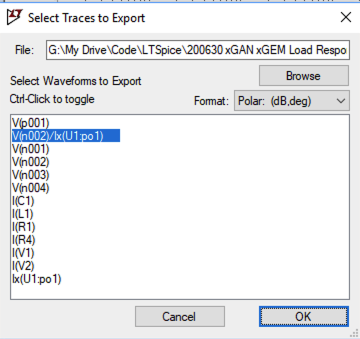

With outputs like this: 

First Line do: "Freq.	V(n002)/Ix(U1:po1)"

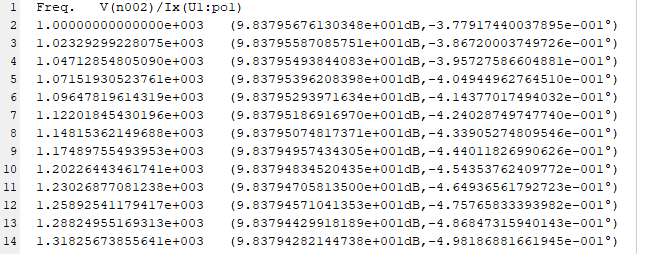

And plots it for us in MATLAB

filenameAdd = '200701 xGAN xGEM Freq Response.txt';
% Single line version exports just raw frequency respnse
% !!!!!!! Must replace top line with 'Freq.	V(n002)/Ix(U1:po1)' !!!!!!!!!
    Data = LT_Freq2Table(filenameAdd)
    % Data = table2array(Data);
    freq = Data(:,'Freq');
    MagZ_out_dB = Data(:,'n002');
    AngZ_out = Data(:,'U1po1');
    freq = table2array(freq);
    MagZ_out_dB = table2array(MagZ_out_dB);
    AngZ_out = table2array(AngZ_out);
    MagZ_out = 10.^(MagZ_out_dB/20)
    
    loglog(freq, (MagZ_out))
    
    samplePt = 1001; %pt 1001 = 100MHz = 124.78298 ohm directly
    freqSample = freq(samplePt)
    zSample = MagZ_out(samplePt) % convert from dB to normal!s
    % z = 1/(2pi*f*C)lead to
    C_eff = 1/(2*pi*freqSample*abs(zSample))
    
    resFreq = 1.0694652e9; %GHz
    % w^2 = 1/LC
    L_eff = 1/((2*pi*resFreq)^2*C_eff)
    save('200701 xGAN Kimball RLC Full Freq Resp', 'freq', 'MagZ_out')


## Time Domain Constant step exporter

Takes data from batch files in LTSpice and exports

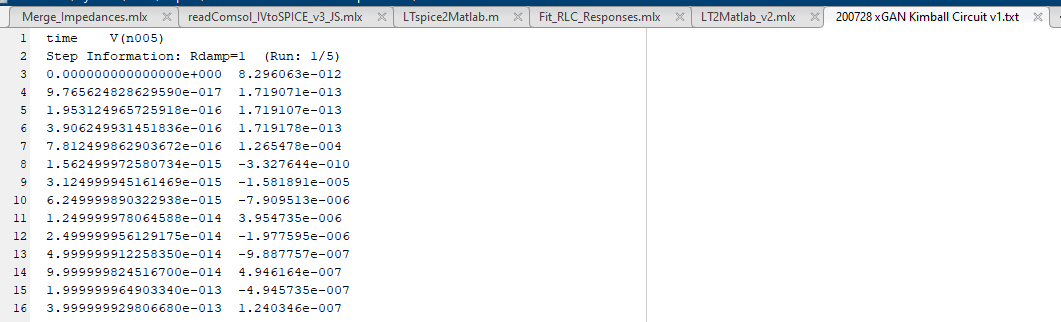

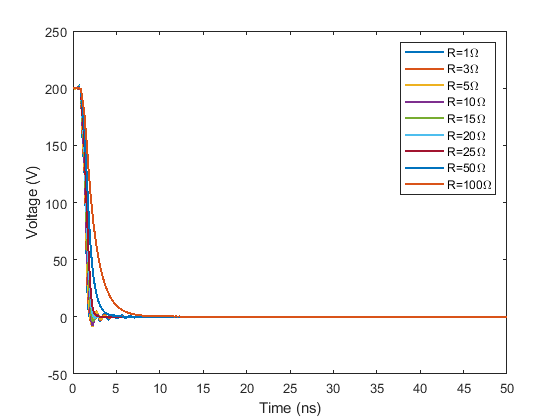

% % % Checks data from current directory with frequency data 
% % Files = dir;
% % checkThis = 2; % which file to read/look at
% % name = Files(checkThis).name;
% 
name = '200728 xGAN Kimball Circuit v4.txt';
fileID = fopen(name,'rt');
formatSpecVars = '%s\t%s';
formatSpecStep = 'Step Information: Rdamp=%f  (Run: %d/%d)';
formatSpecData = '%f\t%f';

    
varName = textscan(fileID, formatSpecVars, 1);  % pulls out variable name
stepName = textscan(fileID, formatSpecStep);    % pulls out run information 
stepR(1) = stepName{1,1};                           % pulls out run resistance
stepMax = stepName{1,3};                         % pulls out max step number
stepData = textscan(fileID, formatSpecData);
stepData = cell2mat(stepData);

% Time axis for interpolation of data
timeRes = 50E-12; % 20GHz total BW (10Ghz positive)
interpMethod = 'linear'; %pchip linear

% number of points (must round to real number
numIntPts = round(((stepData(end,1)-stepData(1,1))/timeRes)+1); % number of interpolated points

% time vector
interpTime = linspace(stepData(1,1), stepData(end,1), numIntPts);

% interpolates voltages
interpVolt = interp1(stepData(:,1),stepData(:,2),interpTime, interpMethod); %interpolates time

interpVoltAll = zeros(stepMax,numIntPts);
interpVoltAll(1, :) = interpVolt;

% loops through steps
if (1) %multiple steps
    for stepNum = 2:stepMax                             %start from 2 since run 1 above
        stepName = textscan(fileID, formatSpecStep);    % read step line
        stepR(stepNum) = stepName{1,1};                 % extracts resistance     
        stepData = textscan(fileID, formatSpecData);
        stepData = cell2mat(stepData);                  % converts to array

        interpVoltAll(stepNum, :) = interp1(stepData(:,1),stepData(:,2),interpTime);
   
    end
end

% rLegend = 'R = ' + int2str(stepR);
plot(interpTime/c.nano, interpVoltAll, "LineWidth", 1.5)
xlabel('Time (ns)')
ylabel('Voltage (V)')
rNames = string(stepR);
legend('R=' + rNames +'\Omega')

% 
fclose(fileID);
% 
% figure()
% titleText = ['File ', name];
% plot(time, voltage);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);


## Symmetrize Outputs for Fourier Analysis and Save

interpVoltAllDbl = [interpVoltAll, interpVoltAll(1)-interpVoltAll(:,2:end)]

Unrecognized function or variable 'interpVoltAll'.

interpTimeDbl = [interpTime, interpTime(2:end) + interpTime(end)]
plot(interpTimeDbl,interpVoltAllDbl)

% save symmetrized data
save("200728 xGAN Symmetric Kimball Sweep v4.mat", "stepR", "interpTimeDbl", "interpVoltAllDbl");

## Convert COMSOL Transfer Function 

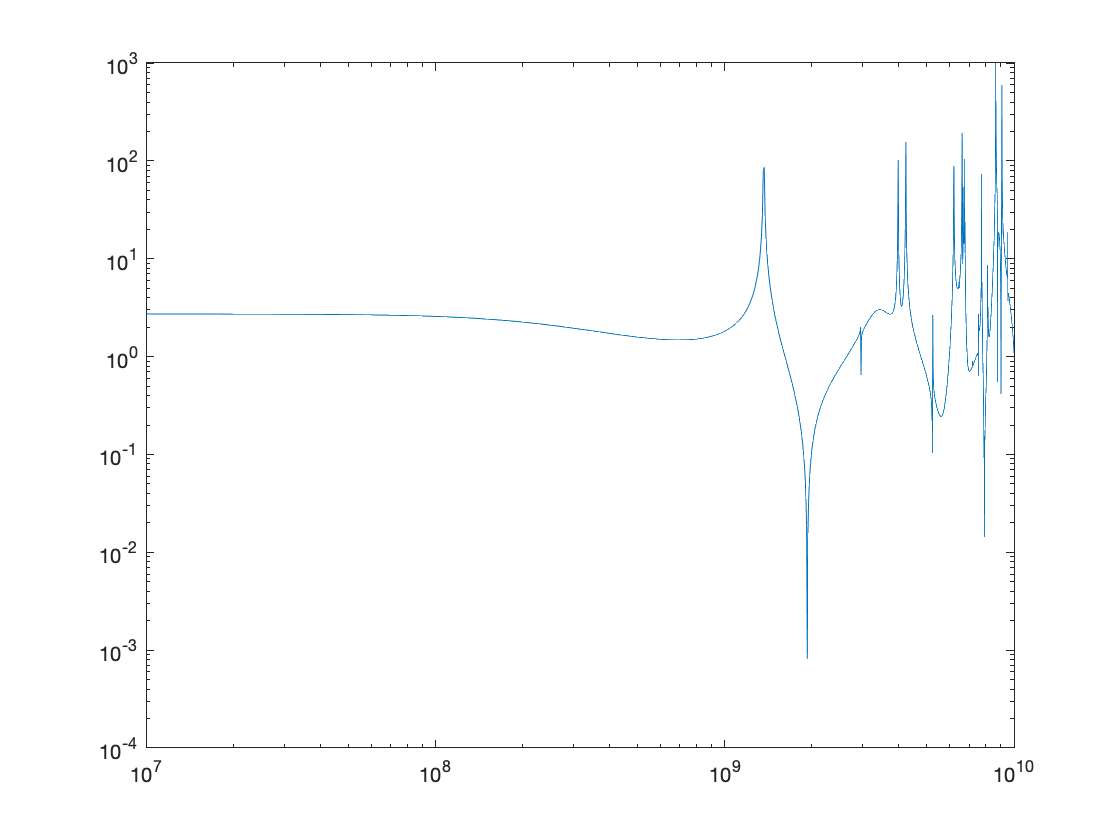

filename='kimballCenterFieldTF_10MHz_10GHz.txt';
fileID=fopen(filename);
headers=textscan(fileID,'%s',1,'delimiter','\n','HeaderLines',8);
headers=char(headers{1});
fseek(fileID,0,'bof');
rawPoints=textscan(fileID,'%f','HeaderLines',9);
rawPoints=rawPoints{1};
rawPoints=rawPoints(4:end);
fclose(fileID);
freqIndex=strfind(headers,'=');
freqSteps=zeros(length(freqIndex),1);%sscanf(headers(timeIndex(1)+1:end),'%f');
for n=1:length(freqIndex)
    if freqIndex(n)<(length(headers)-20)
        freqSteps(n)=sscanf(headers(freqIndex(n)+1:freqIndex(n)+20),'%f',1);
    else
        freqSteps(n)=sscanf(headers(freqIndex(n)+1:end),'%f',1);
    end
end
fieldsVsFreq=zeros(length(rawPoints)/7,9); %time,Ex,Ey,Ez,|E|,Vport,Vnode
perpPlaneFieldRF=zeros(length(rawPoints)/7,1); %magnitude of field components in plane perpendicular to optical axis (y-z)
n=1;
k=1;
while k<=(length(rawPoints)/7)
    fieldsVsFreq(k,1)=freqSteps(n);
    fieldsVsFreq(k,2)=rawPoints(n); %ex
    fieldsVsFreq(k,3)=rawPoints(n+1); %ey
    fieldsVsFreq(k,4)=rawPoints(n+2); %ez
    fieldsVsFreq(k,5)=sqrt(fieldsVsFreq(k,2)^2+fieldsVsFreq(k,3)^2+fieldsVsFreq(k,4)^2); %e magnitude
    fieldsVsFreq(k,6)=rawPoints(n+3); %node 1 voltage
    fieldsVsFreq(k,7)=rawPoints(n+4); %ideal voltage supply
    fieldsVsFreq(k,8)=rawPoints(n+5); %node 2 voltage
    fieldsVsFreq(k,9)=rawPoints(n+6); %voltage at port
    perpPlaneFieldRF(k)=sqrt(abs(fieldsVsFreq(k,3))^2+abs(fieldsVsFreq(k,4))^2);
    n=n+7; 
    k=k+1;
end

% Look at transfer Function
loglog(fieldsVsFreq(:,1),abs(fieldsVsFreq(:,2)))

## Symmetrize Fields to Negative Frequencies

comsolFreqStep=fieldsVsFreq(2,1)-fieldsVsFreq(1,1)

comsolFreqStep = 10000000

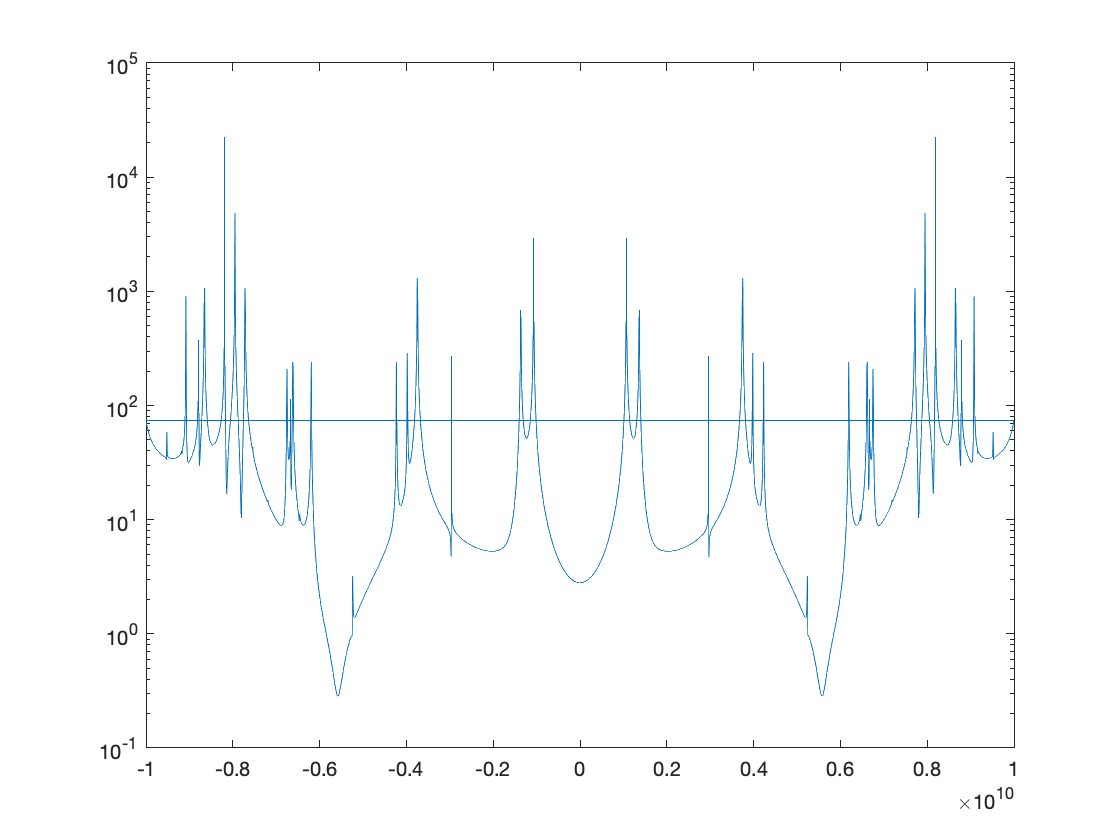

posFreq=fieldsVsFreq(:,1);
% posFreqPad=transpose((posFreq(end)+comsolFreqStep):comsolFreqStep:highestFreq);
% posFreq=[posFreq;posFreqPad];
negFreq=-1*flip(posFreq);
mirrorTFpos=(fieldsVsFreq(:,5)./fieldsVsFreq(:,9));%/length(posFreq);
% mirrorTFposPad=mirrorTFpos(end)*ones(length(posFreqPad),1);
mirrorTFpos=[mirrorTFpos];
mirrorTFneg=flip(conj(mirrorTFpos));
comsolFreq=[posFreq;negFreq];
mirrorTF=[mirrorTFpos;mirrorTFneg];
semilogy(comsolFreq,abs(mirrorTF))

## Generate and Plot LTSpice Output FT

## Generate Fourier Transform of LTSpice Output

workspaceName='200728 xGAN Symmetric Kimball Sweep.mat';
load(workspaceName);
r=7;%which damping resistor 
vLoadRaw=transpose(interpVoltAllDbl(r,:));
timeRaw=transpose(interpTimeDbl);
% time=downsample(timeRaw,5);
% vLoad=downsample(vLoadRaw,5);
time=decimate(timeRaw,7);
vLoad=decimate(vLoadRaw,7);

T=mean(diff(time)); %time iterations
BW=1/(2*T);
Fs=1/T; %sampling frequency
L=length(time);
padLength=floor(L/2)*100;
[trash,midVidx]=min(abs(vLoad-mean(vLoad)));
shift=floor(L/2)-midVidx;
padFront=vLoad(1)*ones(shift+padLength/2,1);
padEnd=vLoad(end)*ones(-shift+padLength/2,1);
vLoadPad=[padFront;vLoad;padEnd];
timePad=T*transpose(0:length(vLoadPad)-1);
Lpad=length(timePad);
fPos=(0:(Lpad/2-1))*(Fs/Lpad);
fNeg=((-Lpad/2):-1)*(Fs/Lpad);
f=transpose([0:Lpad/2-1, -Lpad/2:-1]*(Fs/Lpad));
vLoadTF=fft(vLoadPad,length(f));

## Extra Functions

if(0) % shuts off everything below here

## Code from GitHub

[https://github.com/PeterFeicht/ltspice2matlab.git](https://github.com/PeterFeicht/ltspice2matlab.git)

% Very nice converter from Github!!

% !!!!!!!!!!! Can NOT do steps.. sadly !!!!!!!!!!

addpath('C:\Users\johns\Documents\Github\ltspice2matlab') 
addpath('G:\My Drive\Code\LTSpice\200630 xGAN xGEM Load Responses V0')
% function raw_data = LTspice2Matlab( filename, varargin )
%    Calling Convention:
%        RAW_DATA = LTspice2Matlab( FILENAME );                  % Returns all variables found in FILENAME
%                             (or)
%        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS );   % Returns only selected variables
%               Set SELECTED_VARS to [] to quickly determine the number and names of variables present in
%               FILENAME without actually loading the variables.
%                             (or)
%        RAW_DATA = LTspice2Matlab( FILENAME, SELECTED_VARS, N );
%               Returns variables listed in SELECTED_VARS, with all waveforms downsampled by N. Set N > 1 to
%               load very large data files using less memory, at the price of degraded waveform accuracy and
%               possible aliasing.

filename = '200728 xGAN Kimball Circuit v1.raw'
% rawData = LTspice2Matlab( filename, [] )

rawData = LTspice2Matlab( filename, [10])

rawData.variable_name_list % V(n005) is column 10

time = rawData.time_vect;
voltage = rawData.variable_mat;
plot(time, voltage)

% R = 20;
% RString = num2str(R);
% saveName = "KimbalDampingR" + RString +'.mat';
% save(saveName, 'time', 'voltage')

## Interpolate to constant time step!

% timeRes = 10E-12; % 10ps time resolution
% interpTime = linspace(time(1), time(end), (time(end)-time(1))/timeRes+1);
% interpVolt = interp1(time,voltage,interpTime, 'PCHIP');
% 
% figure(2)
% titleText = ['Interpolated File ', name];
% plot(interpTime, interpVolt);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);


## Original Method Direct Read

% % Checks data from current directory with frequency data 
% Files = dir;
% checkThis = 2; % which file to read/look at
% name = Files(checkThis).name;
% 
% fileID = fopen(name,'rt');
% formatSpec = '%f\t%f';
% 
% %A = fscanf(fileID,formatSpec)
% titles = textscan(fileID, '%s\t%s', 1);
% data = textscan(fileID, formatSpec);
% tit1 = titles{1};
% tit2 = titles{2};
% tit1 = tit1{1};
% tit2 = tit2{1};
% 
% time = data(1);
% voltage = data(2);
% time = time{1}';
% voltage = voltage{1}.';
% 
% fclose(fileID);
% 
% figure(1)
% titleText = ['File ', name];
% plot(time, voltage);
% title(titleText);
% xlabel(tit1);
% ylabel(tit2);
% 


end